## **HCP532 Visualization of Node Measure Assignments For All Eight Conditions**

This script builds a positive and negative Node-Measure Assignment (NMA) for the complete main sample (HCP532, no cross-validation) and plots them.

Before running this script: 

- Run all scripts in HCP Data Prep

- Run setup_data & example from visualization folder 

**1. Prepare the coupling data**

1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_rest_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP{i,j} = x(j,:);
    end
end


1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 532*8 Matrix for each Node)

n = size(Node_all_baseline_HCP,2);
All_Nodes_complete_HCP = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP{j} = vertcat(Node_all_baseline_HCP{:,j});
end 

1.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_HCP{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_4_measures{1,i} = four_measures_per_node;
end

**2. Assign the behavioral variables **

Intelligence_HCP = HCP_behavioral_532.gscore;
Age_HCP = HCP_behavioral_532.Age_in_Yrs;
Gender_HCP = HCP_behavioral_532.gender_num;
Motion_HCP = HCP_behavioral_532.mean_mean_RMS_rest;
Handedness_HCP = HCP_behavioral_532.Handedness;

**3. Build a positive and negative node-measure-assignment**

3.1. For each node, correlate coupling-measure specific coupling values with general intelligence scores

% Preallocation

Correlation_com_measures_fold_rho = zeros(358,4);
Correlation_com_measure_fold_pval = zeros(358,4);

for i = 1:358 % do for each node separately
    All_Communication_measures_per_node = All_Nodes_complete_HCP_4_measures{1,i};
    
     for p = 1:4 % correlate each measure with cognitive ability scores
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_HCP];
                z = [Age_HCP, Gender_HCP, Motion_HCP, Handedness_HCP]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

        
    end
end

3.2. Find out which coupling measure has the highest positive association with general intelligence

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_HCP_wei{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_HCP_wei{i,2} = Idx_max_rho;
end

3.3. Find out which coupling measure has the highest negative association with general intelligence 

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_HCP_wei{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_HCP_wei{i,2} = Idx_min_rho;
end


3.4. Save the node measure assignments 

best_performing_measure_per_node_pos_HCP_wei = cell2mat(Info_best_performing_communication_measure_pos_HCP_wei(:,2)')

best_performing_measure_per_node_pos_HCP_wei =      3     4     1     3     1     4     1     1     1     3     2     1     1     3     3     1     2     1     1     4     4     1     2     4     1     2     2     2     2     4     4     4     1     4     4     3     4     3     1     4     1     2     1     4     3     1     1     4     1     2


best_performing_measure_per_node_neg_HCP_wei = cell2mat(Info_best_performing_communication_measure_neg_HCP_wei(:,2)')

best_performing_measure_per_node_neg_HCP_wei =      1     2     3     1     3     3     4     3     4     2     4     3     2     1     2     4     3     4     3     2     2     4     1     3     3     4     4     1     4     3     1     1     4     2     2     4     1     1     4     2     2     4     3     2     2     2     2     3     3     3


**4. Insert zeros at 120 and 300 **

4.1. Positive NMA 

a = best_performing_measure_per_node_pos_HCP_wei;
b = 0;
idx_120 = 120; 
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

best_performing_measure_per_node_pos_HCP_360_wei = a;

4.2. Negative NMA 

a = best_performing_measure_per_node_neg_HCP_wei; 
b = 0;
idx_120 = 120; 
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

best_performing_measure_per_node_neg_HCP_360_wei = a;

**5. Plot the NMA's **

5.1. Positive NMA

best_performing_measure_per_node_pos_HCP_360_wei(120) = NaN;
best_performing_measure_per_node_pos_HCP_360_wei(300) = NaN;

1 (Path Length) = 100

2 (Communicability) = 200

3 (Cosine Distance) = 300

4 (Search Information) = 4   

vector_pos_bcs = best_performing_measure_per_node_pos_HCP_360_wei;

% All Measures
vector_pos_bcs(vector_pos_bcs == 1) = 100; % path length
vector_pos_bcs(vector_pos_bcs == 2) = 200; % communicability
vector_pos_bcs(vector_pos_bcs == 3) = 300; % cosine distance
vector_pos_bcs(vector_pos_bcs == 4) = 400; % search information

annotName = 'hcp-mmp-b';
dataVec = vector_pos_bcs

dataVec =    300   400   100   300   100   400   100   100   100   300   200   100   100   300   300   100   200   100   100   400   400   100   200   400   100   200   200   200   200   400   400   400   100   400   400   300   400   300   100   400   100   200   100   400   300   100   100   400   100   200


ans = struct with fields:
      border: 1
        cMap: [11×3 double]
      newFig: 1
    valRange: [100 400]
    viewcMap: 1
     viewStr: 'all'


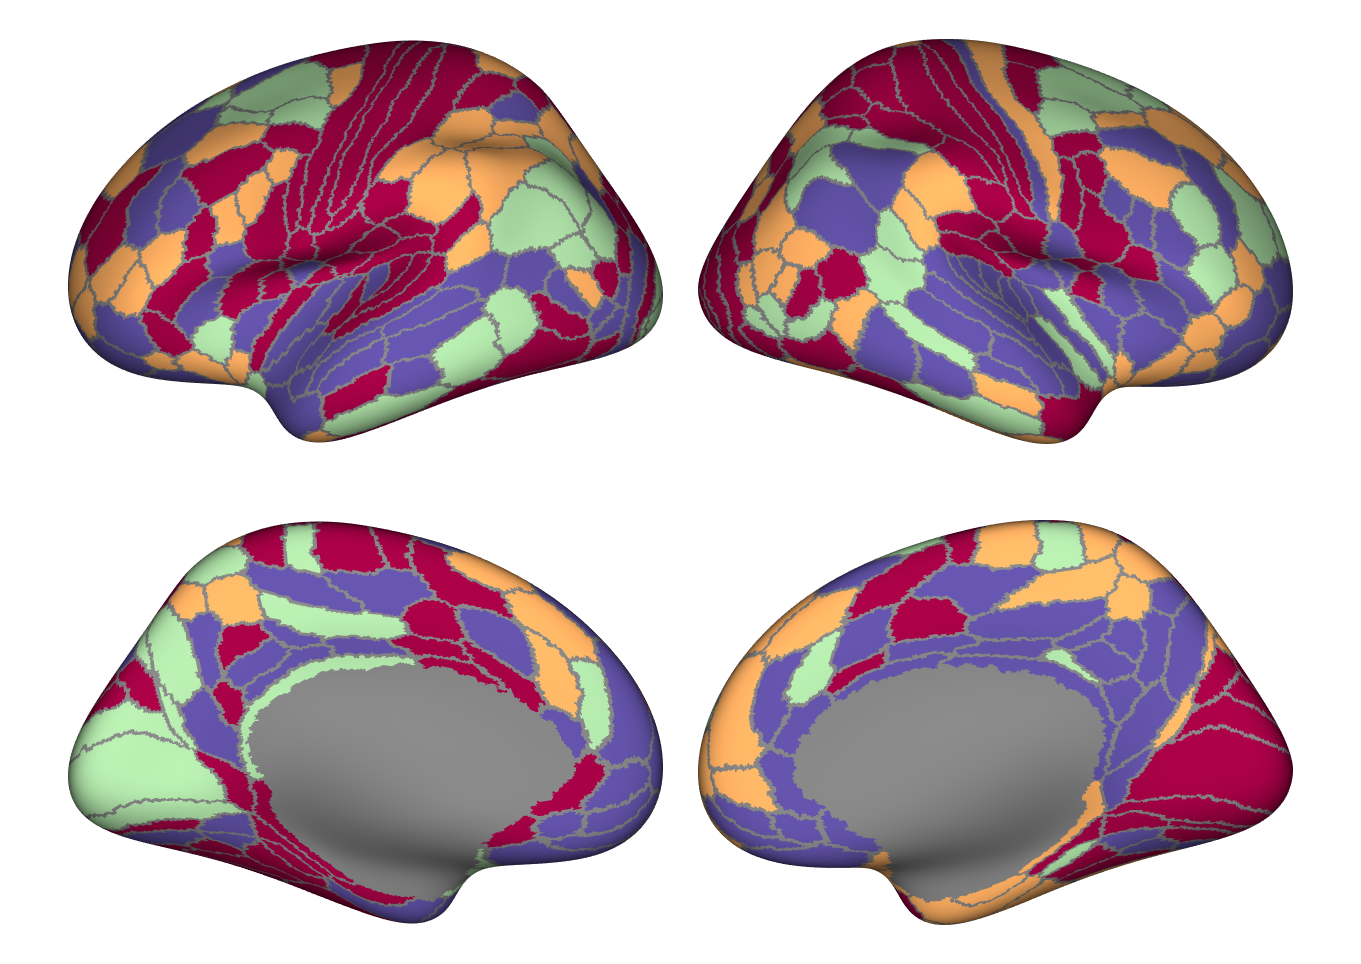

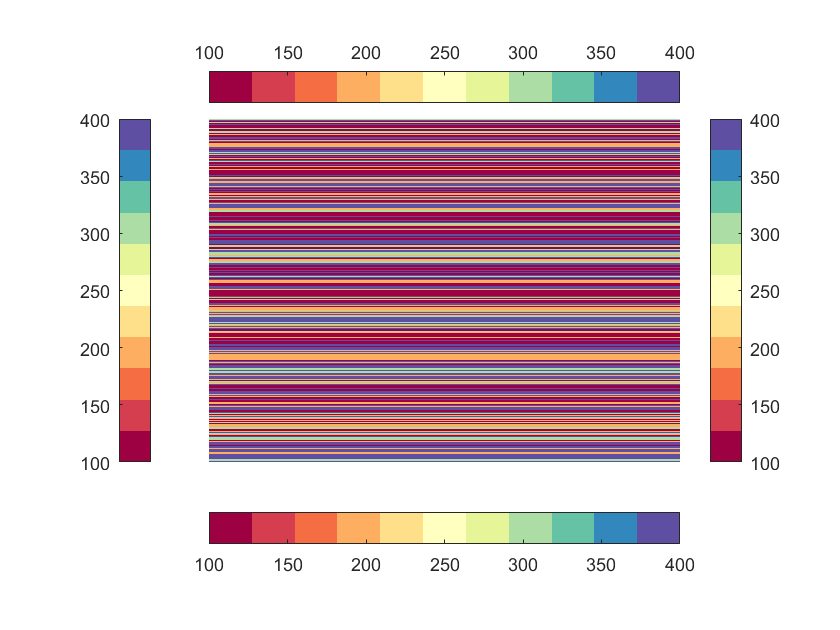

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(11,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100 400]))

5.2. Negative NMA

best_performing_measure_per_node_neg_HCP_360_wei(120) = NaN;
best_performing_measure_per_node_neg_HCP_360_wei(300) = NaN; 


1 (Path Length) = 100

2 (Communicability) = 200

3 (Cosine Distance) = 300

4 (Search Information) = 4   

vector_neg_bcs = best_performing_measure_per_node_neg_HCP_360_wei;

% Diffusion
vector_neg_bcs(vector_neg_bcs == 1) = 100; % path lengh
vector_neg_bcs(vector_neg_bcs == 2) = 200; % communicability
vector_neg_bcs(vector_neg_bcs == 3) = 300; % cosine distance
vector_neg_bcs(vector_neg_bcs == 4) = 400; % search information

annotName = 'hcp-mmp-b';
dataVec = vector_neg_bcs

dataVec =    100   200   300   100   300   300   400   300   400   200   400   300   200   100   200   400   300   400   300   200   200   400   100   300   300   400   400   100   400   300   100   100   400   200   200   400   100   100   400   200   200   400   300   200   200   200   200   300   300   300


ans = struct with fields:
      border: 1
        cMap: [11×3 double]
      newFig: 1
    valRange: [100 400]
    viewcMap: 1
     viewStr: 'all'


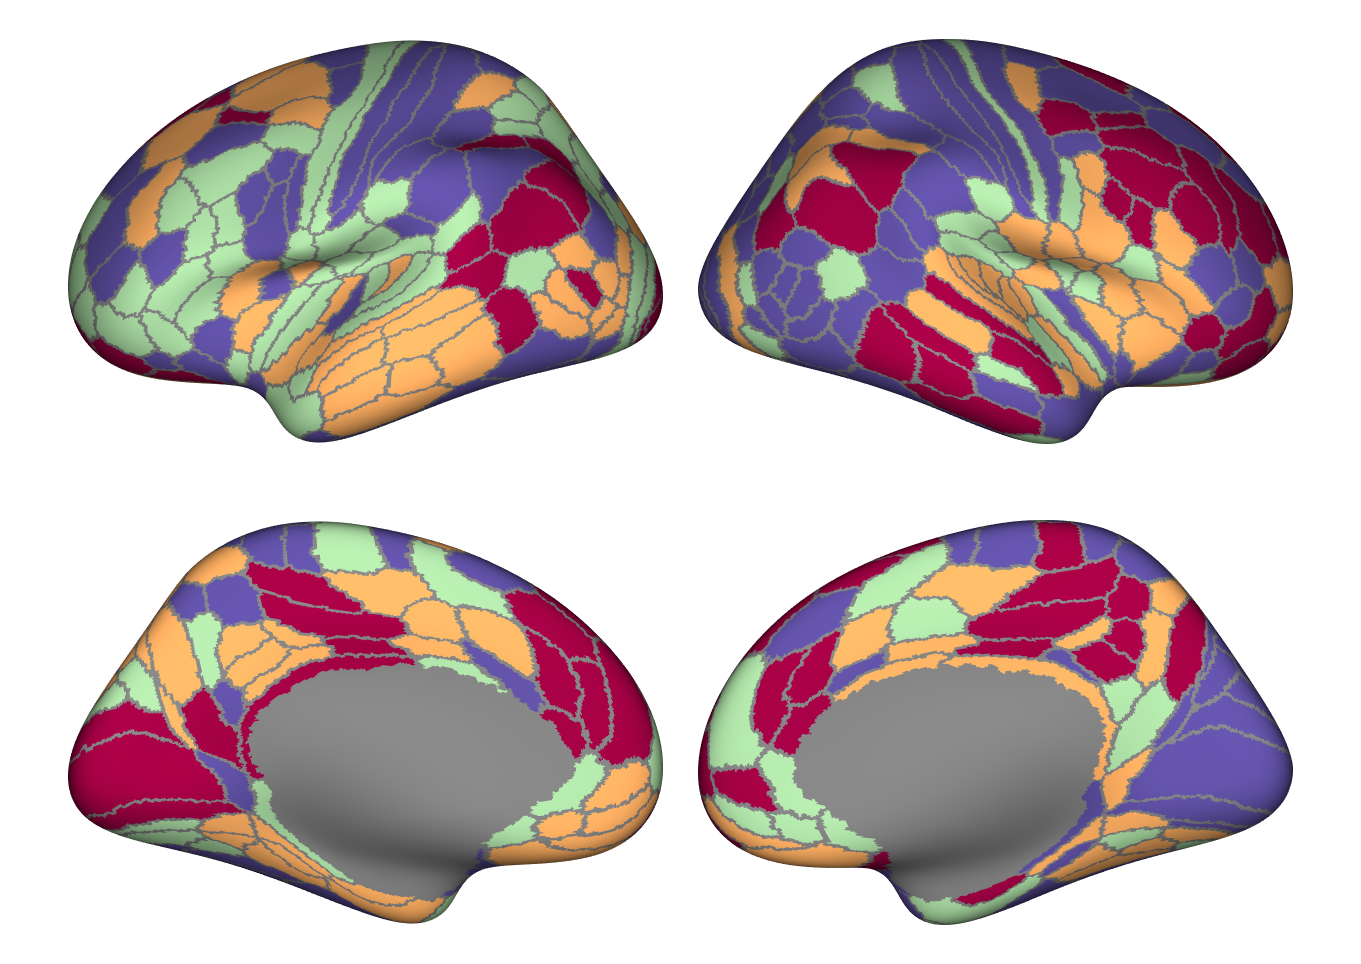

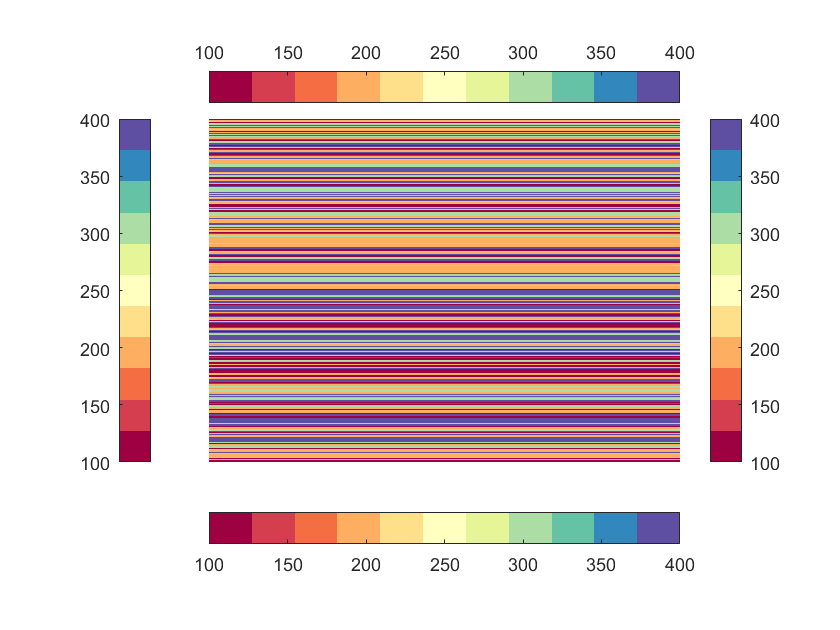

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(11,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100 400]))